## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for complex formation (4 species) is already implemented with the name as ``func_varusai15_s4``, provided by Prof. Baum, saved in the path for models as above.

However, when testing, I found out it does not work because there is no knonlin 3 parameters in the previous function. Fixed version is written here:

function [dx,J] = func_varusai15_s4_fix(t,x,klin,knonlin)
% klin = [k1 k2 k3 k4]
% knonlin = [kn1 kn2 kn3] where kn3 is the deactivation scaling factor

k1 = klin(1); k2 = klin(2); k3 = klin(3); k4 = klin(4);
kn1 = knonlin(1); kn2 = knonlin(2); kn3 = knonlin(3);
dx = zeros(4,1);

A = x(1); B = x(2); AB = x(3); Bs = x(4);

dx(1) = -k1*A*B + k2*AB; % A
dx(2) = -k1*A*B + k2*AB + k3*A*Bs/(Bs+kn1) - k4*kn3*B/(B+kn2); % B
dx(3) =  k1*A*B - k2*AB; % AB
dx(4) = -k3*A*Bs/(Bs+kn1) + k4*kn3*B/(B+kn2); % B*

end

Parameters:

% Parameters from supplementary material
s_star = [5, 300, 0.0001, 0.01]';  % Initial concentrations of A, B, AB, and B*
k1 = 0.021458;       % Rate constant for complex formation
k2 = 0.000227335;    % Rate constant for complex dissociation
k3 = 663.297;        % Rate constant for activation
k4 = 0.000139797;    % Rate constant for deactivation
kn1 = 55.5913;       % Michaelis constant for activation
kn2 = 10.2194;       % Michaelis constant for deactivation
kn3_unstimulated = 1.0;  % Scaling factor for deactivation under unstimulated conditions
kn3_stimulated = 20.0;   % Scaling factor for deactivation under stimulation
params_unstimulated = [k1, k2, k3, k4, kn1, kn2, kn3_unstimulated];
params_stimulated = [k1, k2, k3, k4, kn1, kn2, kn3_stimulated];
klin = [k1, k2, k3, k4]; knonlin_unstimulated = [kn1, kn2, kn3_unstimulated]; knonlin_stimulated = [kn1, kn2, kn3_stimulated];


## 2. Result reproduction

### Temporal dynamics

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 5000, 1001);
t_perb = 0.2 % where pertubation happens

t_perb = 0.2000

opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_varusai15_s4_fix(t,x,klin, knonlin_unstimulated), tspan, s_star, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

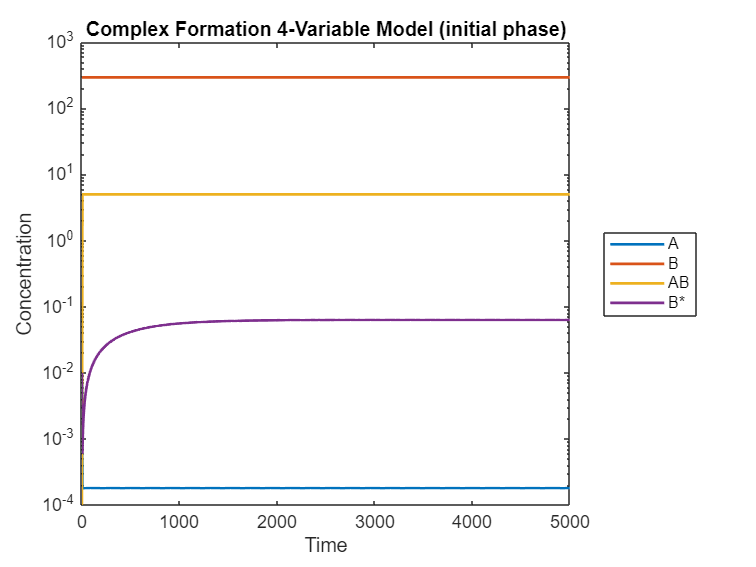

figure;
semilogy(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,5000]);
title('Complex Formation 4-Variable Model (initial phase)');
legend('A','B','AB','B*','Location','eastoutside'); % southeast

QC block:

y0 = s_star_2(:);

f_un = func_varusai15_s4_fix(0, y0, klin, knonlin_unstimulated);
f_st = func_varusai15_s4_fix(0, y0, klin, knonlin_stimulated);

disp([f_un f_st f_st - f_un])   % columns: unstim, stim, difference

    0.0000    0.0000         0
   -0.0000   -0.0026   -0.0026
   -0.0000   -0.0000         0
    0.0000    0.0026    0.0026



disp(norm(f_st - f_un))

    0.0036



Now, draw temporal dynamics for unstimulated conditions from t=[-1000, 0], and then stimulated conditions from t=[0, 2000].

tspan_1 = linspace(-1000, 0, 500);
tspan_2 = linspace(0, 2000, 1000);
[t_un, sol_unstimulated] = ode15s(@(t,x) func_varusai15_s4_fix(t,x,klin, knonlin_unstimulated), tspan_1, s_star_2, opts);
[t_sti, sol_stimulated] = ode15s(@(t,x) func_varusai15_s4_fix(t,x,klin, knonlin_stimulated), tspan_2, sol_unstimulated(end,:), opts);

t_all = [t_un; t_sti(1:end)];
sol_all = [sol_unstimulated; sol_stimulated(1:end,:)];

Plot

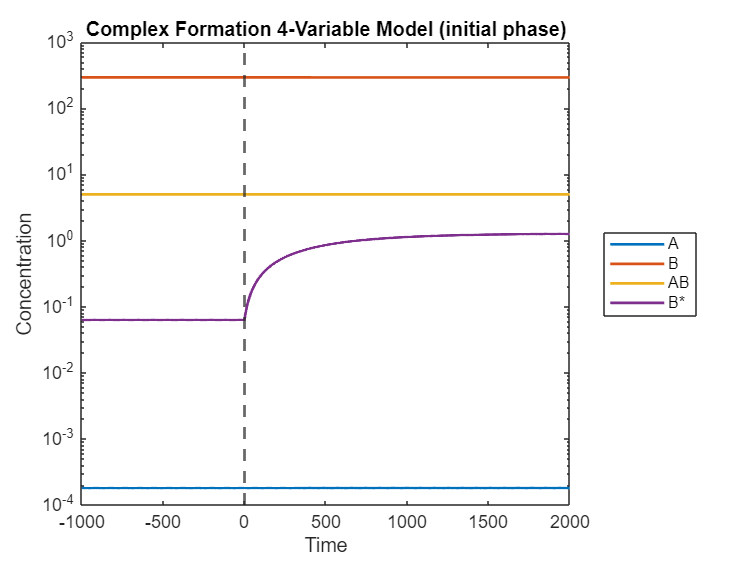

figure;
semilogy(t_all, sol_all, 'LineWidth', 1.5);
xline(0, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([-1000,2000]);
title('Complex Formation 4-Variable Model (initial phase)');
legend('A','B','AB','B*','Location','eastoutside'); % southeast

### **Detect loop structure change:**

j_0_un = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_unstimulated),s_star_2);
signed_j_0_un =sign(j_0_un)

signed_j_0_un =     -1    -1     1     0
    -1    -1     1     1
     1     1    -1     0
    -1     1     0    -1



j_0_sti = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_stimulated),sol_stimulated(end,:));
signed_j_0_sti =sign(j_0_sti)

signed_j_0_sti =     -1    -1     1     0
     1    -1     1     1
     1     1    -1     0
    -1     1     0    -1


for k = 1:numel(t_all)
    t = t_all(k);
    y = sol_all(k, :);  % 4x1 state at time t

    % choose params by time (stimulus at t=0)
    if t < 0
        knonlin_use = knonlin_unstimulated;
    else
        knonlin_use = knonlin_stimulated;
    end

    % Jacobian at this state
    j_matrix_t = numerical_jacobian_complex( ...
        @(x) func_varusai15_s4_fix(1, x, klin, knonlin_use), ...
        y);

    % signed Jacobian at this time
    signed_jacobian_t = sign(j_matrix_t);

    % Compare with baseline signed structure
    if ~isequal(signed_jacobian_t, signed_j_0_un)
        fprintf('At time %.2f after the stimulus, the signed Jacobian structure changes.\n', t);

        loop_list_t = find_loops(j_matrix_t);

        fprintf('Jacobian matrix at time %.2f:\n', t);
        disp(j_matrix_t);

        fprintf('Signed Jacobian matrix at time %.2f:\n', t);
        disp(signed_jacobian_t);

        fprintf('Loop summary at this time:\n');
        disp(loop_summary(loop_list_t));

        break
    end
end

At time 234.23 after the stimulus, the signed Jacobian structure changes.


Jacobian matrix at time 234.23:


   -6.3188   -0.0000    0.0002         0
    0.0232   -0.0000    0.0002    0.0021
    6.3188    0.0000   -0.0002         0
   -6.3420    0.0000         0   -0.0021



Signed Jacobian matrix at time 234.23:


    -1    -1     1     0
     1    -1     1     1
     1     1    -1     0
    -1     1     0    -1



Loop summary at this time:


                length_1    length_2    length_3    length_4
                ________    ________    ________    ________

    total          4           4           3           1    
    negative       4           1           1           1    
    positive       0           3           2           0    



### **Plot:**

colors = [
    0.5 0.5 0.5;   % gray
];

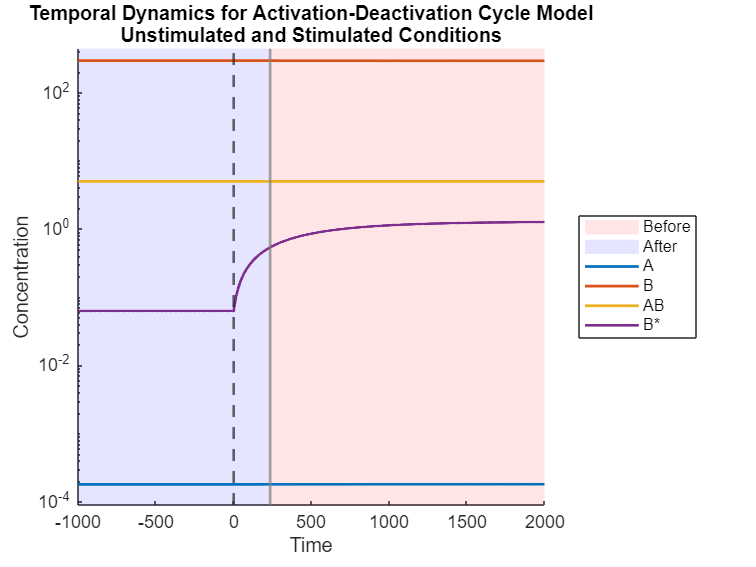

t_change = t;              % <-- the time when structure changes
tmin = t_all(1);
tmax = t_all(end);

figure;
ax = axes; hold(ax,'on');
xline(ax, t, '-', 'LineWidth', 1.5, 'Color', colors(1,:));

% set axes to log scale 
set(ax,'YScale','log');

% Plot your trajectories
h = semilogy(ax, t_all, sol_all, 'LineWidth', 1.5);

% Limits
xlim(ax, [-1000 2000]);
ylim(ax, [min(sol_all(:))*0.5, max(sol_all(:))*1.5]);  % or just ylim(ax,'auto')
yl = ylim(ax);

% shaded region BEFORE change (blue, alpha 0.1)
p1 = patch(ax, ...
    [tmin t_change t_change tmin], ...
    [yl(1) yl(1) yl(2) yl(2)], ...
    'b', 'FaceAlpha', 0.10, 'EdgeColor', 'none');

% shaded region AFTER change (red, alpha 0.1) ---
p2 = patch(ax, ...
    [t_change tmax tmax t_change], ...
    [yl(1) yl(1) yl(2) yl(2)], ...
    'r', 'FaceAlpha', 0.10, 'EdgeColor', 'none');

% Put patches behind the lines
uistack(p1,'bottom');
uistack(p2,'bottom');

% Vertical line at stimulus time (optional)
xline(ax, 0, '--', 'LineWidth', 1.5);

xlabel(ax,'Time');
ylabel(ax,'Concentration');
title(ax, ['Temporal Dynamics for Activation-Deactivation Cycle Model' newline ...
          'Unstimulated and Stimulated Conditions']);

legend(ax, {'Before','After','','A','B','AB','B*'}, 'Location','eastoutside');

### **Dynamics of B**

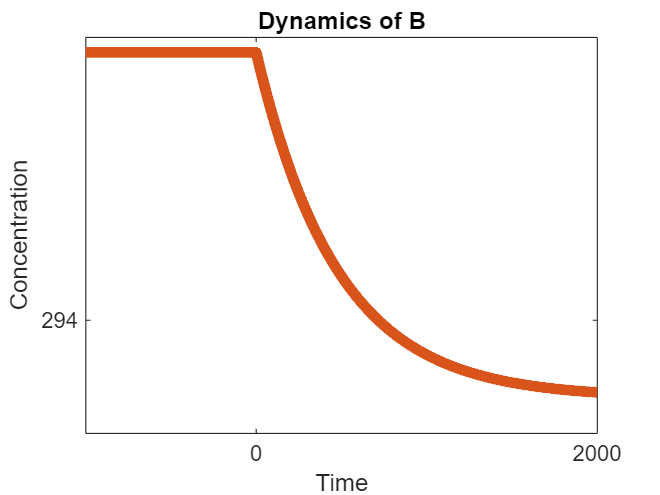

figure('Position',[100 100 400 300]);  % similar size to figsize=(4,3)

% Plot only B (column 2)
plot(t_all, sol_all(:,2), ...
     'LineWidth', 5, ...
     'Color', [0.85 0.33 0.10]);  

xlim([-999 2000]);

% Show only 0 and 2000 on x-axis
xticks([0 2000]);

% Match Python: np.arange(293,295,1)
yticks(293:1:294);

xlabel('Time');
ylabel('Concentration');
title('Dynamics of B');

box on

### **Loop structure:**

**Unstimulated condition:**

loop_list_un=find_loops_vset(@(x)func_varusai15_s4_fix(1,x,klin, knonlin_unstimulated),s_star_2',100); 
% max_num_loops does have effect in the final summary like in R
disp(loop_list_un{1})

        loop         length    sign
    _____________    ______    ____

    {[    2 1 2]}      2         1 
    {[  3 1 2 3]}      3        -1 
    {[    3 1 3]}      2         1 
    {[  3 2 1 3]}      3        -1 
    {[    3 2 3]}      2         1 
    {[  4 2 1 4]}      3         1 
    {[4 2 3 1 4]}      4        -1 
    {[    4 2 4]}      2         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 



disp(loop_summary(loop_list_un{1}))

                length_1    length_2    length_3    length_4
                ________    ________    ________    ________

    total          4           4           3           1    
    negative       4           0           2           1    
    positive       0           4           1           0    



**Stimulated condition:**

loop_list_sti=find_loops_vset(@(x)func_varusai15_s4_fix(1,x,klin, knonlin_stimulated),sol_stimulated(end,:)',100);
disp(loop_list_sti{1})

        loop         length    sign
    _____________    ______    ____

    {[    2 1 2]}      2        -1 
    {[  3 1 2 3]}      3         1 
    {[    3 1 3]}      2         1 
    {[  3 2 1 3]}      3        -1 
    {[    3 2 3]}      2         1 
    {[  4 2 1 4]}      3         1 
    {[4 2 3 1 4]}      4        -1 
    {[    4 2 4]}      2         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 



disp(loop_summary(loop_list_sti{1}))

                length_1    length_2    length_3    length_4
                ________    ________    ________    ________

    total          4           4           3           1    
    negative       4           1           1           1    
    positive       0           3           2           0    



### **Jacobian matrix:**

j_0_un = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_unstimulated),s_star_2);
signed_j_0_un =sign(j_0_un)

signed_j_0_un =     -1    -1     1     0
    -1    -1     1     1
     1     1    -1     0
    -1     1     0    -1



j_0_sti = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_stimulated),sol_stimulated(end,:));
signed_j_0_sti =sign(j_0_sti)

signed_j_0_sti =     -1    -1     1     0
     1    -1     1     1
     1     1    -1     0
    -1     1     0    -1


## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_3_complex_formation_extend.mlx", "MATLAB/model_3_complex_formation_extend.pdf")

path = 'MATLAB\model_3_complex_formation_extend.pdf'

mdfile = export("MATLAB/model_3_complex_formation_extend.mlx","MATLAB/model_3_complex_formation_extend.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_3_complex_formation_extend.md'